# **HOW TO CALL PYTHON LIBRARY FUNCTION IN MATLAB (BASIC)**

Kevin Chng

Application Engineer

kevin.chng@techsource-asia.com

## Overview :

        In this script, it explains how to call python library function in MATLAB for window users. It follows the documentation of MATLAB in the link below:

[https://www.mathworks.com/help/matlab/call-python-libraries.html](https://www.mathworks.com/help/matlab/call-python-libraries.html)

Therefore, if you have went through the mentioned documentation, then this script does not have value for you. In the zip file, it has python script, hence you don't need to write the python script yourself, I hope it will facilitate your learning.

**[ You must go through this script section by section, some steps required you manually to complete it ]**

## **Highlights :**

In this script, it provide you the basicinformation regarding

- System and Configuration Requirements

- Understanding Python and MATLAB import Cammands

- Call User-Defined Python Module

- Reload Modified User-Defined Python Module

- Help for Python Functions

- Create a Python object

- Additional Information - for complicated interaction

- What's next? 

## **Product Focus :**

- MATLAB

**Written at 5 October 2018**

## **System and Configuration Requirements**

Do not bother what version of python your colleagues are using first. First, we install the compatible python in our laptop as MATLAB user. 

Not all version python supported by MATLAB. Currently, there are 3 versions supported which are **Version 2.7, Version 3.5 and Version 3.6. **

I recommend you to download the installer Python 3.6 from the link below.

[https://www.python.org/downloads/](https://www.python.org/downloads/)

I have encoutered an error before because there are incompatible version of python installed in my pc previously. Therefore, I recommend you to unistall all the python version first, then later install the compatible version of python.

% Remind you to do installation first
uiwait(msgbox('Have you done the installation?'));

After you completed the installation, run

pyversion


       version: '3.6'
    executable: 'C:\Program Files (x86)\Microsoft Visual Studio\Shared\Python36_64\pythonw.exe'
       library: 'C:\Program Files (x86)\Microsoft Visual Studio\Shared\Python36_64\python36.dll'
          home: 'C:\Program Files (x86)\Microsoft Visual Studio\Shared\Python36_64'
      isloaded: 0



If it returns empty answer or error, then you can't proceed. Recommend you to post your error or reason in MATLAB community to seek for help.

[https://www.mathworks.com/matlabcentral/](https://www.mathworks.com/matlabcentral/)

% Remind you to do installation first
uiwait(msgbox('Please ensure there is proper response from pyversion command?'));

## Short Brief before proceeding

## **Understanding Python and MATLAB import Cammands**

In python, they will import the package or library first to access the code before coding. However, in MATLAB, it does not work this way. If you use MATLAB, it is importing function.

In my personal opinion, ignore it as beginnner. If you go deeper, you may refer to this link : [https://www.mathworks.com/help/matlab/matlab_external/python-import-and-matlab-import-commands.html](https://www.mathworks.com/help/matlab/matlab_external/python-import-and-matlab-import-commands.html)

## What are python's object, class and method?

[https://www.hackerearth.com/practice/python/object-oriented-programming/classes-and-objects-i/tutorial/\](https://www.hackerearth.com/practice/python/object-oriented-programming/classes-and-objects-i/tutorial/\)

## **Call User-Defined Python Module**

In the zip file, there are wirtten python scripts, however, I will explain how I generate the python script here first.

**How to generate python script?**

1) Open a text file, then copy the script below put into text file. 

In the script, it means that the module has 2 methods which are search and theend.

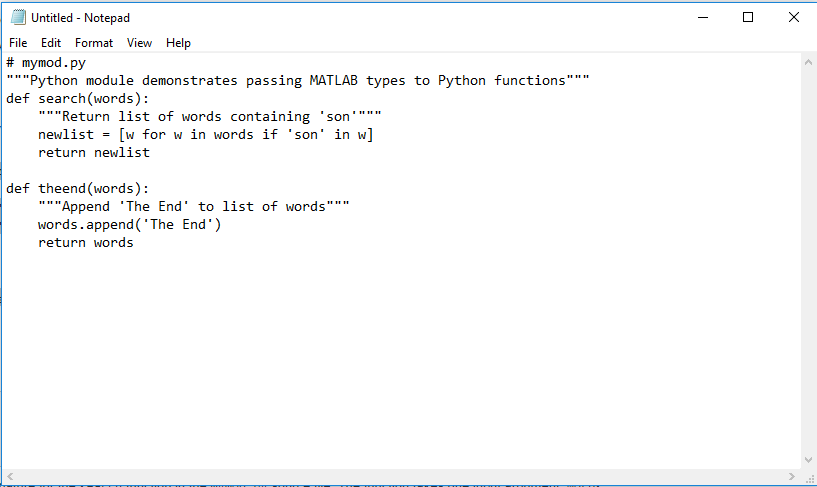

Save the text file as mymod.py.  Remember to change your *save as type *to all file. 

Store the mymod.py in the location same as your MATLAB working path.

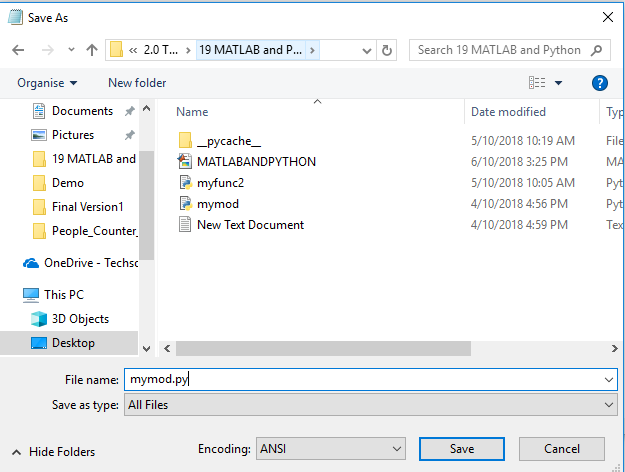

Done. You will realize that an empty text file is existed. You just need to delete it.

**Call the generated py. script>**

In the mymod.py, for the two methods inside the mymod module/class, it needs one argument as input for the function.

MATLAB variable will not working with your python module/class. Therefore, we have to generate a python variables in MATLAB for the input.

Here is the interesting part, **how do you put input variable for the python function?**

There are 2 ways :

1) Direct put MATLAB variables, let try it out.

matlabvariable = {'Jones','Johnson','James'};
py.mymod.search(matlabvariable)

ans =   Python list with no properties.

    ['Johnson']


Yeah, it is working well. How about another function in the module? Uncommand the py.mymod.theend(matlabvariable), then run it.

%py.mymod.theend(matlabvariable)

Why is there an error ? 

It is because, it will automatically help you convert the type of your MATLAB variables to certain python type.

Refer to the link below:

[https://www.mathworks.com/help/matlab/matlab_external/passing-data-to-python.html](https://www.mathworks.com/help/matlab/matlab_external/passing-data-to-python.html)

In the link, you will find that the cell type of MATLAB will automatically converted to tuple type. In python, tuple  type don't have append function/method. 

2) Create python variable in MATLAB and then put it as argument to call python function/method

pythonvariable = py.list({'Jones','Johnson','James'});
py.mymod.search(pythonvariable)

ans =   Python list with no properties.

    ['Johnson']


py.mymod.search(pythonvariable)

ans =   Python list with no properties.

    ['Johnson']


Both functions are working well. It is always better to create python variable and then put it as argument to avoid any unexpected changes due to MATLAB automatically convert the data type.

However, for MATLAB numeric variable, it should not have any problem. By default, when you pass a MATLAB number to a Python function/method, Python reads it as a float.

**How to use the returned value/variables from python function?**

It should not be part of tutorial for beginner. However, i feel it is neccesary to give some tips on how to start off this part.

Open this link [https://www.mathworks.com/help/matlab/python-data-types.html](https://www.mathworks.com/help/matlab/python-data-types.html)

In the link, you focus on the keyword 'Use', then you will see 

1) Use Python str Type in MATLAB

2) Use Python list Type in MATLAB

3) Use Python list Type in MATLAB

4) Use Python list of Numeric types in MATLAB

5) Use Python List as Values in for Loop

6) Use Python dict Type in MATLAB

7) Use Python Numeric Types in MATLAB

8) Use Python array Types in MATLAB

Let me use numeric type example here, it is relatively easier to be understand.

I generated a python script (numerictype.py), you may find it in the attached.

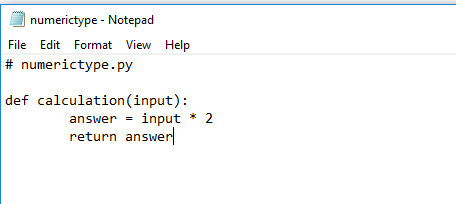

As mentioned, if numeric variable, it should be fine for us to use MATLAB varibales directly instead of generate python variables

output = py.numerictype.calculation(5)

output = 10

From the result, you will notice MATLAB again automatic to convert the result of python to MATLAB type . 

Link for reference : [https://www.mathworks.com/help/matlab/matlab_external/handling-data-returned-from-python.html#buialof-53](https://www.mathworks.com/help/matlab/matlab_external/handling-data-returned-from-python.html#buialof-53)

However, MATLAB will not automatically convert all the return result to MATLAB type.

for example , [https://www.mathworks.com/help/matlab/matlab_external/use-python-array-array-types.html](https://www.mathworks.com/help/matlab/matlab_external/use-python-array-array-types.html)

For myself, as MATLAB user, i'm not familiar as well, however, those link explain well. If i forgot how to use the returned python list, then I will refer to the mentioned link.

## **Call Modified User-Defined Python Module**

**How about your colleague wanted to modify the script? Or you want to modify the script?**

Here is another interesting part. Let say your MATLAB is on, and you modify your python script. 

Let modify the script and save it. You can either run the code below to change your python script, or change it manually.

file = fileread('numerictype.py');
  k=strfind(file, '2');
  file(k);
  file(k) = '3';

file =     '# numerictype.py
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     
     def calculation(input): 
     
     
     
     
     
     
     
     
     
     
     
     
     	answer = input * 3 
     
     
     	return answer'


fid = fopen('numerictype.py', 'wt');
fprintf(fid, '%s',file);
fclose(fid);

if you want change it manually, open numerictype.py as text file, then edit the number 2 to 3, then save as numerictype.py.

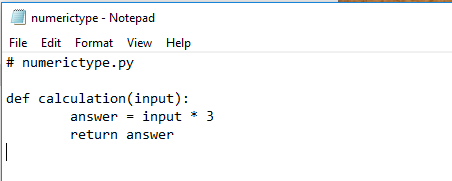

After modifying the code, then try run again

output = py.numerictype.calculation(5)

output = 10

if we change 2 to 3, the output should be 15 because 5x3=15. So **what is the reason? **

There is some technical reason here, MATLAB save them as cache. if you want to mak your changes make effect, then there are two ways:

1) restart your MATLAB

2) or reload the modified Python script/module.

warning('off')
clear classes
mod = py.importlib.import_module('numerictype');
%if you use Python 3.x version. In first part, we install Python 3.6
py.importlib.reload(mod);
% if you use, then replace the lind of code above with py.reload(mod);

After reload the module, then you should able to get the correct result from the modified script/module

output = py.numerictype.calculation(5)

output = 15

the first line 'clear classes' is very important. You may try dont clear classes, but you will not get the result from updated Python script/module.

## **Help for python function**

Refer to [https://www.mathworks.com/help/matlab/matlab_external/help-for-python-functions.html,](https://www.mathworks.com/help/matlab/matlab_external/help-for-python-functions.html,)

how to call help for python in MATLAB.

py.help('numerictype.calculation')

Help on function calculation in numerictype:

numerictype.calculation = calculation(input)
    Input Numeric Variable



Then it will return what is description for function-calculation in the module. 

**How about those in-built python function?**

% Package
py.help('textwrap')

Help on module textwrap:

NAME
    textwrap - Text wrapping and filling.

CLASSES
    builtins.object
        TextWrapper
    
    class TextWrapper(builtins.object)
     |  Object for wrapping/filling text.  The public interface consists of
     |  the wrap() and fill() methods; the other methods are just there for
     |  subclasses to override in order to tweak the default behaviour.
     |  If you want to completely replace the main wrapping algorithm,
     |  you'll probably have to override _wrap_chunks().
     |  
     |  Several instance attributes control various aspects of wrapping:
     |    width (default: 70)
     |      the maximum width of wrapped lines (unless break_long_words
     |      is false)
     |    initial_indent (default: "")
     |      string that will be prepended to the first line of wrapped
     |      output.  Counts towards the line's width.
     |    subsequent_indent (default: "")
     |      string that will be prepended to all lines save the first


% Class
py.help('textwrap.TextWrapper')

Help on class TextWrapper in textwrap:

textwrap.TextWrapper = class TextWrapper(builtins.object)
 |  Object for wrapping/filling text.  The public interface consists of
 |  the wrap() and fill() methods; the other methods are just there for
 |  subclasses to override in order to tweak the default behaviour.
 |  If you want to completely replace the main wrapping algorithm,
 |  you'll probably have to override _wrap_chunks().
 |  
 |  Several instance attributes control various aspects of wrapping:
 |    width (default: 70)
 |      the maximum width of wrapped lines (unless break_long_words
 |      is false)
 |    initial_indent (default: "")
 |      string that will be prepended to the first line of wrapped
 |      output.  Counts towards the line's width.
 |    subsequent_indent (default: "")
 |      string that will be prepended to all lines save the first
 |      of wrapped output; also counts towards each line's width.
 |    expand_tabs (default: true)
 |      Expand tabs in input

% Method of Class
py.help('textwrap.TextWrapper.wrap')

Help on function wrap in textwrap.TextWrapper:

textwrap.TextWrapper.wrap = wrap(self, text)
    wrap(text : string) -> [string]
    
    Reformat the single paragraph in 'text' so it fits in lines of
    no more than 'self.width' columns, and return a list of wrapped
    lines.  Tabs in 'text' are expanded with string.expandtabs(),
    and all other whitespace characters (including newline) are
    converted to space.



% function
py.help('textwrap.fill')

Help on function fill in textwrap:

textwrap.fill = fill(text, width=70, **kwargs)
    Fill a single paragraph of text, returning a new string.
    
    Reformat the single paragraph in 'text' to fit in lines of no more
    than 'width' columns, and return a new string containing the entire
    wrapped paragraph.  As with wrap(), tabs are expanded and other
    whitespace characters converted to space.  See TextWrapper class for
    available keyword args to customize wrapping behaviour.



## **Create a Python Object**

In MATLAB®, Python objects are *reference types* (handle objects) and do not adhere to the MATLAB copy-on-assignment and pass-by-value rules. When you copy a handle object, only the handle is copied and both the old and new handles refer to the same data.

This example follow documentation : [https://www.mathworks.com/help/matlab/matlab_external/create-object-from-python-class.html.](https://www.mathworks.com/help/matlab/matlab_external/create-object-from-python-class.html.)

It called a default Python object,

tw = py.textwrap.TextWrapper

tw =   Python TextWrapper with properties:

        break_on_hyphens: 1
       subsequent_indent: [1×0 py.str]
                   width: [1×1 py.int]
             expand_tabs: 1
    fix_sentence_endings: 0
             placeholder: [1×6 py.str]
               max_lines: [1×1 py.NoneType]
        break_long_words: 1
         drop_whitespace: 1
          initial_indent: [1×0 py.str]
                 tabsize: [1×1 py.int]
      replace_whitespace: 1



change some value with the object

tw.break_long_words = 0;
class(tw.width);
tw.width = int64(3);

Create a matlab variable, then wrap it with python object

T = 'MATLAB® is a high-level language and interactive environment for numerical computation, visualization, and programming.';
w = wrap(tw,T)

w =   Python list with no properties.

    ['MATLAB®', 'is', 'a', 'high-', 'level', 'language', 'and', 'interactive', 'environment', 'for', 'numerical', 'computation,', 'visualization,', 'and', 'programming.']


Convert it back to MATLAB variable

wrapped = cellfun(@char, cell(w), 'UniformOutput', false);

wrapped = 1×15 cell array
    {'MATLAB®'}    {'is'}    {'a'}    {'high-'}    {'level'}    {'language'}    {'and'}    {'interactive'}    {'environment'}    {'for'}    {'numerical'}    {'computation,'}    {'visualization,'}    {'and'}    {'programming.'}


fprintf('%s\n', wrapped{:})

MATLAB®
is
a
high-
level
language
and
interactive
environment
for
numerical
computation,
visualization,
and
programming.


It is an very interesting example. It demonstrates how to input argument into python method. After we get the returned result from Python method, then it converts the python variable back to MATLAB variable.

## **Additional Information - for complicated interaction**

If there are too many interaction between MATLAB and python, I recommend you to study the tow links below thoroughly.

[https://www.mathworks.com/help/matlab/python-data-types.html](https://www.mathworks.com/help/matlab/python-data-types.html)

[https://www.mathworks.com/help/matlab/calling-python-functions.html](https://www.mathworks.com/help/matlab/calling-python-functions.html)

In MATLAB, there is an eval function which is also can apply on Python. This is how to execute python command in MATLAB but run them in Python.

[https://www.mathworks.com/help/matlab/matlab_external/call-python-eval-function.html](https://www.mathworks.com/help/matlab/matlab_external/call-python-eval-function.html)

However, there is a gentle reminder that MATLAB compiler does not compile python library into it. Therefore, please do not call any python function/method in the script if you want compile it.

## **What's next?**

I will write a script how to call MATLAB compiled Python Package in Python. I guess I will use Machine Learning as example.

 py.qoiread.myfunc2()

Undefined variable "py" or class "py.qoiread.myfunc2".